## Alpha3 oscillators

The alpha3 uses two kinds of oscillators:

- 3 segment multi-shape oscillators (3S): used as the first oscillator of the DCO

- 5 segments multi-shape oscillators (5S): used as the second oscillator of the DCO and the LFOs

Those two kinds of oscillators allow to quickly create variations of the elementary signals (square, sawtooth and triangle), with intermediate results; thus the name "multi-shape".

### 3S oscillator

The 3 segments is basically a square signal that can be transformed thanks to two parameters:

- **Pulse width**: represents the amount of signal with a given amplitude (minimum or maximum)

- **Growth slope** (or simply **slope**): represents how steep is the slope between the minimum amplitude and the maximum amplitude

The oscillator is denoted as "3 segments" because the combination of the pulse width and the slope creates a shape composed of 3 segments:

- Segment 1: a straight line with the minimum amplitude

- Segment 2: a slope that grows fom the minimum to the maximum amplitude

- Segment 3: a straight line with the maximum amplitude

Notice that:

- The shape starts with the minimum amplitude, not the maximum, as usual; the choice is explained later on

- The second segment is non-null if and only if the slope is non nulls

#### 3S pulse width

As mentioned above, the first segment represents the minimum of the amplitude. We assume that:

- The size of this segment can't be less than half of the signal

- When pushed to the maximum value, the oscillation is silent

In this oscillator, the pulse width represents the length of this segment. This is somehow counter-intuitive, in the sense that we imagine the pulse as the moment where the oscillation is at its maximum. This choice is dictated by several decisions:

- Considering the pulse as the minimum or the maximum of the oscillation does not change the output when it's a pure square signal

- By pushing the pulse width and the slope to their maximum, one gets a sawtooth

- Such a sawtooth easily mixes with the second oscillator, in a familiar and intuitive way, which is not necessarily the case with an inverted sawtooth

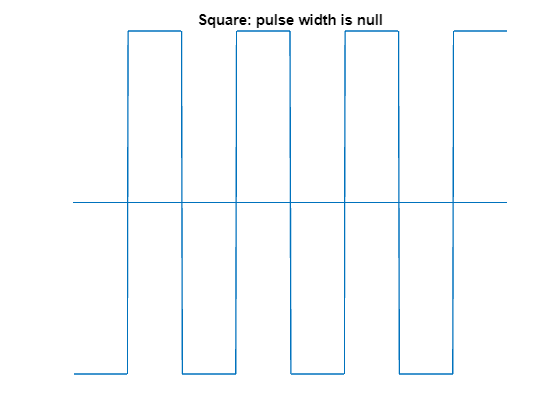

wave_len = 128;
pulse_width = 0;
plot_three_segments_mso(wave_len, pulse_width, 0, 'Square: pulse width is null');

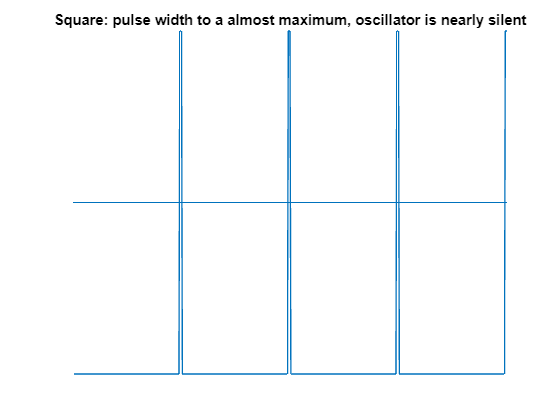

wave_len = 128;
pulse_width = 120;
plot_three_segments_mso(wave_len, pulse_width, 0, 'Square: pulse width to a almost maximum, oscillator is nearly silent');

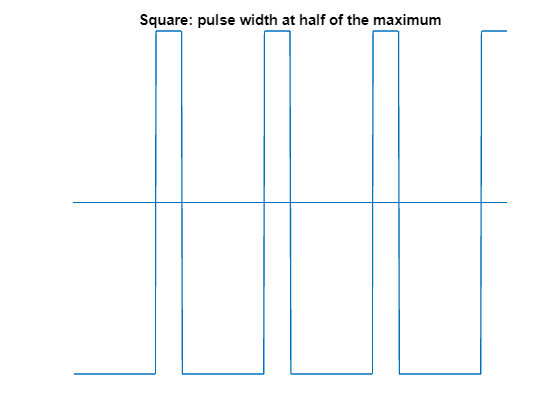

wave_len = 128;
pulse_width = 64;
plot_three_segments_mso(wave_len, pulse_width, 0, 'Square: pulse width at half of the maximum');

#### 3S growth slope

The growth slope defines a percentage of segment 1 to start segment 2. When the slope is null, the signal is a pure square, as illustrated in the above figures. When the slope is at its maximum value, the signal slowly grows to reach the maximum amplitude:

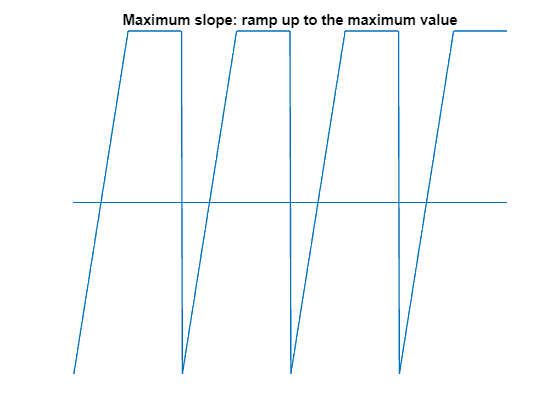

wave_len = 128;
pulse_width = 0;
slope = 127;
plot_three_segments_mso(wave_len, pulse_width, slope, 'Maximum slope: ramp up to the maximum value');

Intermediate slope value maintains the oscillator at its minimum before growing to the maximum value, as illustrated below:

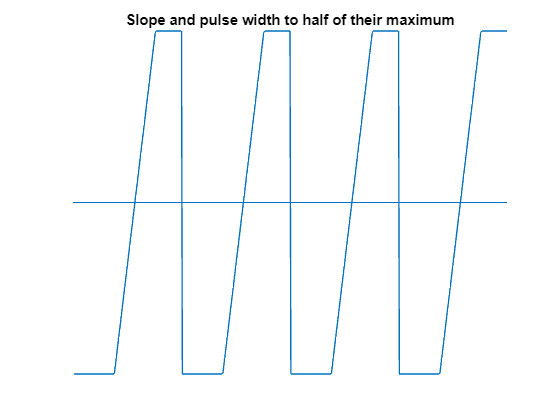

wave_len = 128;
pulse_width = 64;
slope = 64;
plot_three_segments_mso(wave_len, pulse_width, slope, 'Slope and pulse width to half of their maximum');

As expected, pushing the slope and the pulse width to their maximum produces a sawtooth:

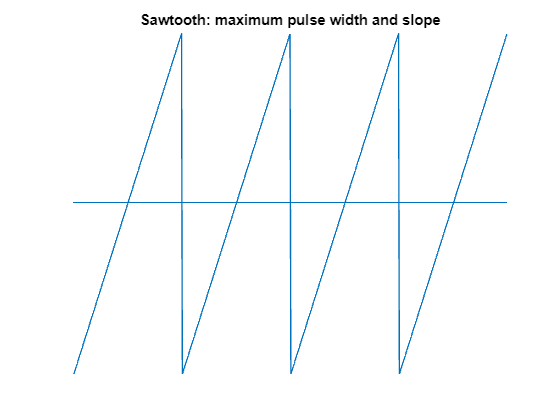

wave_len = 128;
pulse_width = 127;
slope = 127;
plot_three_segments_mso(wave_len, pulse_width, slope, 'Sawtooth: maximum pulse width and slope');

### 5S oscillator

The 5 segments oscillator can generate different kinds of signals and variations of those signals, using two parameters:

- **Pulse width**: represents the position of the point with the maximum amplitude

- **Saturation**: amplifies the basic signal, which becomes saturated

The oscillator is denoted as "5 segments" because the combination of the pulse width and the saturation creates a shape composed of 5 segments:

- Segment 1: a straight line with the minimum amplitude

- Segment 2: a slope that grows from the minimum to the maximum amplitude

- Segment 3: a straight line at the maximum amplitude

- Segment 4: a slope that descends from the maximum amplitude to the minimum amplitude

- Segment 5: a straight line at the minimum amplitude

Notice that segment 1, 3 and 5 are non-null if and only if the signal is saturated.

#### 5S pulse width

Purpose of the pulse width is to create a basic shape that varies from an inverted sawtooth to a sawtooth with an intermediate state representing a triangle. Assuming that no saturation is appied:

- When the pulse width is null, the resulting signal is an inverted sawtooth

- When the pulse width is at half of the frequency, the resulting signal is a triangle

- When the pulse width is at its maximum, the resulting signal is a sawtooth

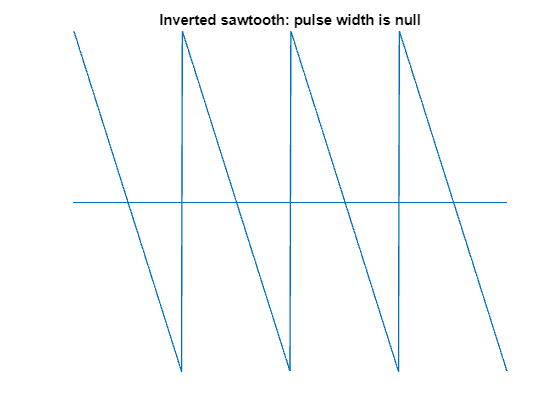

wave_len = 128;
pulse_width = 0;
plot_five_segments_mso(wave_len, pulse_width, 0, 'Inverted sawtooth: pulse width is null');

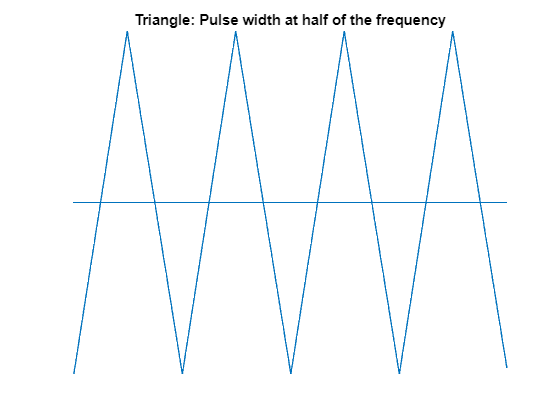

pulse_width = wave_len / 2 -1;
plot_five_segments_mso(wave_len, pulse_width, 0, 'Triangle: Pulse width at half of the frequency');

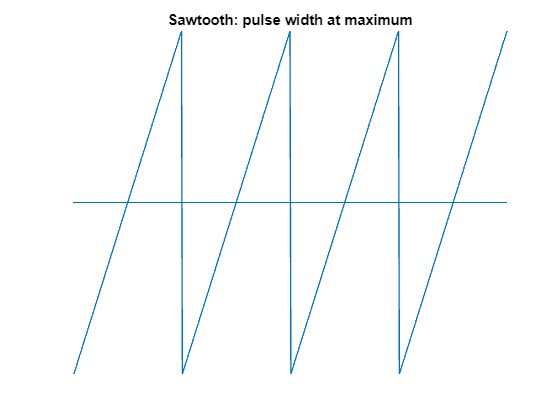

pulse_width = wave_len -1;
plot_five_segments_mso(wave_len, pulse_width, 0, 'Sawtooth: pulse width at maximum');

#### 5S saturation

The saturation amplifies the initial signal, to create the segments 1, 3 and 5 (where the signal is saturated). This way, the oscillators progressively approximates a square signal.

When pushed to its maximum, the saturation gives a very good approximation, as illustrated below:

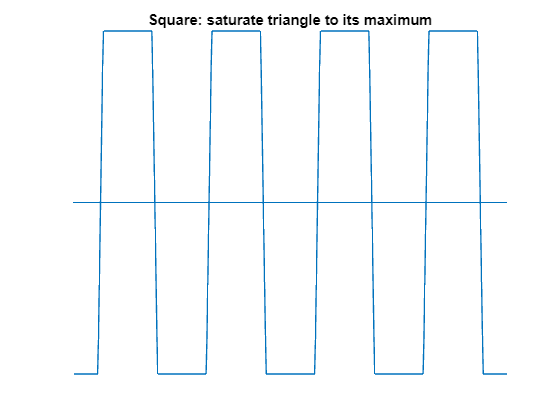

pulse_width = wave_len / 2 -1;
plot_five_segments_mso(wave_len, pulse_width, 127, 'Square: saturate triangle to its maximum');

Notice that you get the same result with an inverted sawtooth and a sawtooth, only the phase of the oscillation is changing:

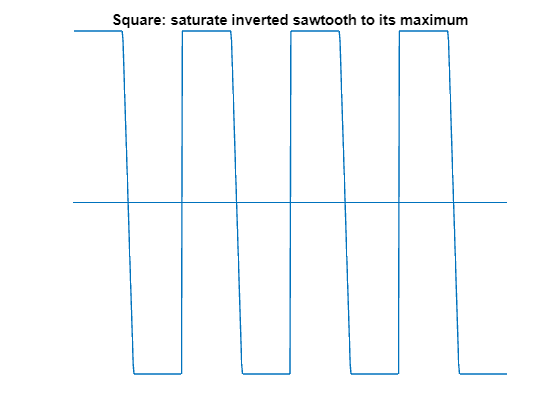

pulse_width = 0;
plot_five_segments_mso(wave_len, pulse_width, 127, 'Square: saturate inverted sawtooth to its maximum');

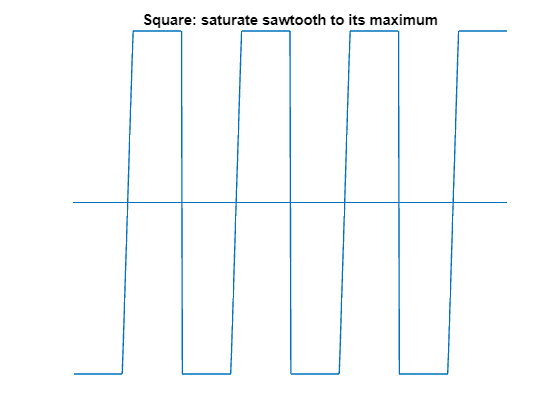

pulse_width = wave_len -1;
plot_five_segments_mso(wave_len, pulse_width, 127, 'Square: saturate sawtooth to its maximum');

Naturally, specifying a lower level of saturation generates smoother oscillations; for example, using only half of the maximum saturation:

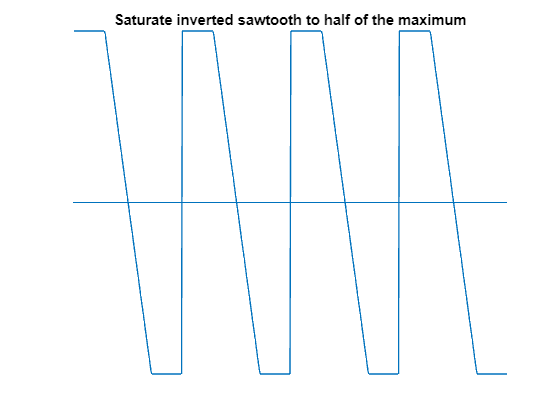

pulse_width = 0;
plot_five_segments_mso(wave_len, pulse_width, 63, 'Saturate inverted sawtooth to half of the maximum');

And notice that, contrary to a classical square oscillator, this saturation does not allow to control the width of the square pulse.

To conclude, one may be interested by the way the signal is saturated:

- The 5S first computes the output with no saturation

- Then it multiplies the result by a *saturation factor*

- And it finally saturates that result

The saturation factor is computed on the basis of a "saturation parameter", between 0 and 127, as follows:


$$S\left(x\right)=\cosh \left(3*\frac{x}{127}\right)$$


Which gives the following result:

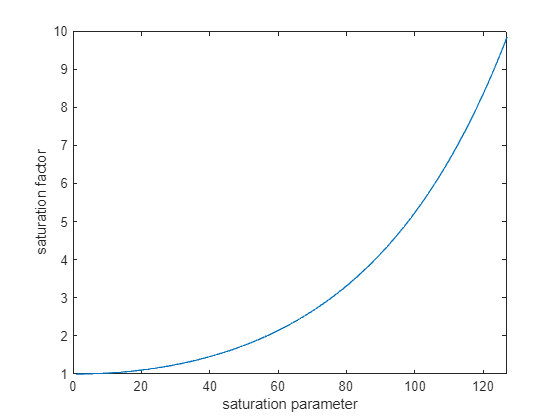

p_sat = linspace(0, 127, 128);
sat = compute_sat_coef(p_sat);
plot(sat);
    xlim([0 127]);
    xlabel('saturation parameter');
    ylabel('saturation factor')

function plot_three_segments_mso(wave_len, p_pulse_width, p_slope, plot_title)
    out = zeros(4*wave_len);
    for i = 0 : 4*wave_len-1
        id = mod(i, wave_len);
        out(i + 1) = three_segments_mso(id, p_pulse_width, p_slope, wave_len);
    end
    plot(out);
    xlim([0 4 * wave_len]);
    %set(gca, 'XTick', []);
    %set(gca, 'YTick', []);
    set(gca, 'XColor', 'none', 'YColor', 'none');
    title(plot_title);
    box off;
end

% TODO would be interesting to make this cleaner and backport to model
function sample = triangle(id, pw, wave_len)
    % The output is a signal in range [-1,1] which is then rescaled wrt
    % saturation
    min = -1;
    max = 1;
    amp = max - min;
    if id < pw
        sample = single(min + amp * id / pw);
    else
        slope = wave_len - pw;
        sample = single(max - amp * (id - pw) / slope);
    end
end

function sat = compute_sat_coef(p_sat)
    scaled = p_sat/127;
    sat = cosh(3 * scaled);
end
function saturated = apply_sat(sample, sat)
    saturated = sat * sample;
    saturated = min(1, saturated);
    saturated = max(-1, saturated);
end

function sample = five_segments_mso(id, pw, p_sat, wave_len)
    sat = compute_sat_coef(p_sat);
    sample = triangle(id, pw, wave_len);
    sample = apply_sat(sample, sat);
end

function plot_five_segments_mso(wave_len, pulse_width, p_sat, plot_title)
    out = zeros(4*wave_len);
    for i = 0 : 4*wave_len-1
        id = mod(i, wave_len);
        out(i + 1) = five_segments_mso(id, pulse_width, p_sat, wave_len);
    end
    plot(out);
    xlim([0 4 * wave_len]);
    %set(gca, 'XTick', []);
    %set(gca, 'YTick', []);
    set(gca, 'XColor', 'none', 'YColor', 'none');
    title(plot_title);
    box off;
end